# Entropic Regression User Guide

## Introduction

In this supplementary document, we provide a user guide for using the ERFit MATLAB package. For the algorithm details of the Entropic Regression, the user can refer for our published paper:

- Abd AlRahman R. AlMomani, Jie Sun, and Erik Bollt, "How Entropic Regression Beats the Outliers Problem in Nonlinear System Identification," Chaos 30, 013107 (2020).

Entropic Regression package provides the user with a wide range of options, and the possibility to perform some operations with a user-defined MATLAB function that follows the same structure of the functions we provide in this implementation.

In this document we explore some of the basic options. However, for the details of the options, see the function $\texttt{eroptset}$ for entropic regression, and the header of the function $\texttt{getSystemDataset}$ for dataset generation options.

## About the Data

Consider the problem of parameters estimation for the system:


$$\dot{x} = f(x,\beta)$$


where $x\in\mathbb{R}^{N\times d}$ is the state variable,  $\dot{x}\in\mathbb{R}^{N\times d}$ is the vector field (underlying dynamic), and $\beta$ is the set of parameters. If $x$ is the only measured quantity, then $\dot{x}$ can be computed by the difference method or total variation method. In modern matrix form we write the problem in the form:


$$\dot{x} = \Phi\beta$$


where $\Phi:\mathbb{R}^{N\times d} \mapsto \mathbb{R}^{N\times K}$ is a function that maps the state variables $X$, to expanded set of candidate functions (not necessarily linear).

Seperate from the regression part, we provide in our package a data generation toolkit, where the user provide only the ode function of the system, and the function $\texttt{getSystemDataset}$ provide all the required data transformation and setting to perform the sparse regression.

We provide the ode functions for Lorenz, Rossler, and Van der Pol system in the toolkit.

In this example, we will consider the Lorenz system as our subject system and the source of observed data.

% Initialize the workspace
clearvars; close all; clc;
addpath('Data Generation')
addpath('erfit tools')

rng(1,'twister'); % For reproducability

Data = getSystemDataset(@lorenzODE);

The structure $\texttt{Data}$ has all the information related to the generated data:

disp(Data)

                 x0: [3×1 double]
             Xclean: [1003×3 double]
                  t: [1003×1 double]
         Xbasenoise: [1003×3 double]
         Xcorrupted: [1003×3 double]
    CorruptionIndex: [1003×1 logical]
               Xdot: [1001×3 double]
                Phi: [1001×35 double]
         PowrMatrix: [35×3 double]
                  h: 0.0100
               eps1: 0.0050
               eps2: 0
               Berp: 0
     ExpansionOrder: 4



where:

$\texttt{x0}$: The initial condition, $\texttt{Xclean}$: is the exact observed data without adding any noise or corruption, $\texttt{t}$: is the time at the sampled observations, $\texttt{Xbasenoise}$: is the data after adding Gaussian noise with zero mean and $\texttt{eps1}$ standart deviation, $\texttt{Xcorrupted}$: is the observations after corrupting a fraction of the data determined by the Bernoulli probability $\texttt{Berp}$ and adding a Gaussian noise with zero mean and $\texttt{eps2}$ standard deviation for the corrupted locations. $\texttt{CorruptionIndex}$ have the indecies of the corrupted observations.

$\texttt{Xdot}$ have the vector field computed on the corrupted and noisy data, and $\texttt{Phi}$ is the power polynomial expansion to the oreder $\texttt{ExpansionOrder}$, and determined by the $\texttt{PowerMatrix}$.

To understand the power matrix, we show some the first few rows for explinations

disp(Data.PowrMatrix(1:6,:))

     0     0     0
     1     0     0
     0     1     0
     0     0     1
     2     0     0
     1     1     0



For the three dimensions Lorenz sysem ( $x,y$ and $z$ ), each column in the power matrix represent the the power of coresponding dimension, and each row, represent a term (column) in the expansion matrix Phi.

For example, the first row in the power matrix is [0 , 0, 0], indicate that the first column in $\texttt{Phi}$ is $[x^0 \times y^0 \times z^0] = 1$, which is the constant term in the expansion matrix.

The $4^{th}$ row in $\texttt{PowerMatrix}$ is [0,  0,  1], which implies that the $4^{th}$ column in $\texttt{Phi}$ is $[x^0 \times y^0 \times z^1] = z$.

Then we can see that:


$$[2,  0,  0] \rightarrow x^2$$


$[1,  2,  0] \rightarrow xy^2$, ans so on.

We used this strategy to make it simple for its computations efficiency and to track which functions we have after the sparse regression solution obtained.

### User Defined Data

To obtain data for other system, the user can call:

Data2 = getSystemDataset(@rosslerODE);
% OR 
Data3 = getSystemDataset(@vanderpol,'dim',2); % default dimension is 3
                                              % for other dimensions we
                                              % provide the dimension as
                                              % input pairs

And for a user defined ODE function, the function should follow the structure similar to lorenzODE.m, or rosslerODE.m provided in this package.

Assume that we wish to obtain data from the system:


$$\dot{x} = x + 2y \\
\dot{y} = 3x - 2y$$


we can write this system as ode as the following:

sys = @(t, x) [(x(1) + 2*x(2));
               (3*x(1) - 2*x(2))];
           

Then we can obtain the dataset by calling:

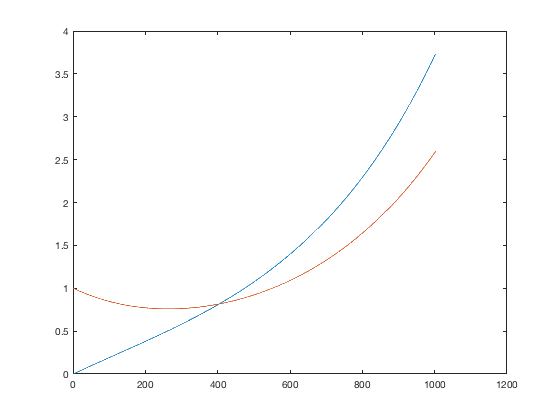

% See the function comments for more detailes in the options
SysData = getSystemDataset(sys,'SampleSize',1000,...
                               'tao',0.001,...
                               'dim',2,...
                               'initCondition', [0; 1],...
                               'skipTrans',false); 
plot(SysData.Xclean)

## Effict of Noise and Outliers

In many approaches, the derivative computed from the clean and exact measurements in the matrix $X$, and the noise added only to the derivative (in analogy to the traditional linear algebra formulation $y = Ax + \epsilon$ where the noise appear only on $y$). 

However, such approaches have poor reliability when we attempt to discover the underlying dynamics in the form of a set of ODEs, where the only measured quantity is the state variable $X$, and naturally, it should be the noisy measurements.

To see the effect of noise and corruption, consider the data:

Data = getSystemDataset(@lorenzODE, 'SampleSize', 10000,...
                                   'tao', 0.001,...
                                   'eps1',0.005,...
                                   'Berp', 0.25,...
                                   'eps2',0.1);
                               

In the above code, we created 5000 data pints from Lorenz system with 0.001 time step (tao), and the data have noise of $\texttt{eps1}$ standard deviation, and 25% of the data are corrupted with Gaussian noise of $\texttt{eps2}$ standard deviation. 

One may think that a noise with 0.1 standard deviation in the state variable is relativeley low, however, note that the drivative and the basis matrix are created out of this noisey data. To see the effect of such noise on the sparse regression problem, we take look on the vector field time series:

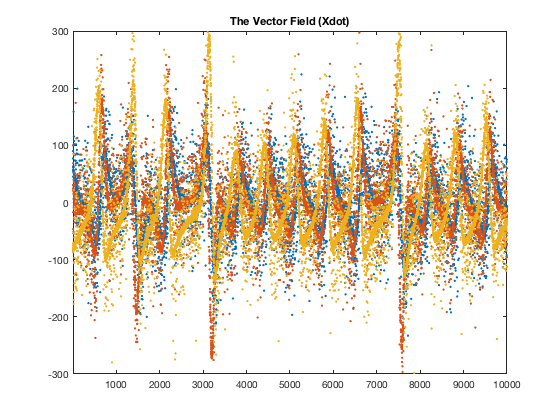

figure
plot(Data.Xdot,'.')
title('The Vector Field (Xdot)')
axis([1 10000 -300 300])

## Entropic Regression

### Simple Call

Now, we create a data for regression purpose. For simplicity, the function $\texttt{getSystemDataset}$ can be called with different output combination to provide the data of interest directly. For example:

[Phi,Xdot,DInfo] = getSystemDataset(@lorenzODE,...
                       'SampleSize',1000,'eps1',0.005);  
                   

Generates 1000 noisy data points of Lorenz, with the dictionary and the vector field directly provided in Phi, and Xdot matricies. All other info are stored in DInfo structure.

Now, we can simply apply the entropic regression by

[S, ERInfo] = erfit(Phi,Xdot);

where S have the final sparse solution, and ERInfo structure have information about the regression process:

disp(ERInfo)

         estimatedTolerence: [0.0735 0.0739 0.0730]
       ForwardSelectedIndex: {[3 2]  [30 2 7 3]  [27 20 15 5 10 29 6 4]}
             ForwardSuccess: [1 1 1]
    BackwardEliminatedIndex: {[1×0 double]  [30]  [5 10 15 20 27 29]}
                      Index: {[2 3]  [1 2 7 3]  [1 6 4]}
                          S: {[2×1 double]  [4×1 double]  [3×1 double]}



and the sparse solution is:

disp(S)

         0    0.0150    0.0208
   -9.9793   27.7361         0
    9.9790   -0.9391         0
         0         0   -2.6601
         0         0         0
         0         0    0.9966
         0   -0.9926         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
        

### Dynamics Reproduction

To reproduce the dynamic from  the solution obtained from erfit, we provide the function $\texttt{getODEHandle}$ which returns ODE function handle from a given spase solution and the power matrix:

odefun = getODEHandle(DInfo.PowrMatrix, S);

Now, we can deal with $\texttt{odefun}$ as any ode function in matlabe. We reproduce the dynamics from the same initial condition as follows:

X = DInfo.Xcorrupted; % the sampled data
x0 = X(1,:)';         % The initial condition
timeStep = DInfo.h;   % time step
N = size(X,1);      % number of sampled points

[t,R] = ode45(odefun, 0:timeStep:(timeStep*(N-1)),x0); %Re-produced dynamic



We visualize the sampled data and reproduced data together as follows

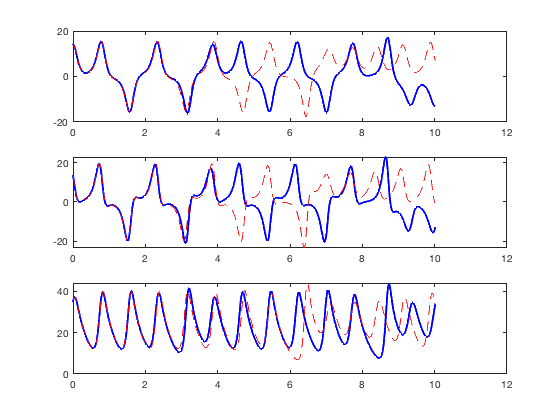

subplot(3,1,1)
plot(t,X(:,1),'-b','LineWidth',2)
hold on
plot(t,R(:,1),'--r','LineWidth',1)

subplot(3,1,2)
plot(t,X(:,2),'-b','LineWidth',2)
hold on
plot(t,R(:,2),'--r','LineWidth',1)

subplot(3,1,3)
plot(t,X(:,3),'-b','LineWidth',2)
hold on
plot(t,R(:,3),'--r','LineWidth',1)

We see how the reproduced dynamic diverges from the original one after about 300 iterations due to the error in the estimated parameters magintude and the synsitivity of chaotic systems to the initial conditions. However, we see clearly that the obtained solution was able to reproduce the general behavior of the dynamic. To this in the long run, in the following we plot the sampled data to the left, and to the right, we plot the reproduced dynamic for much longer time than the sampled data:

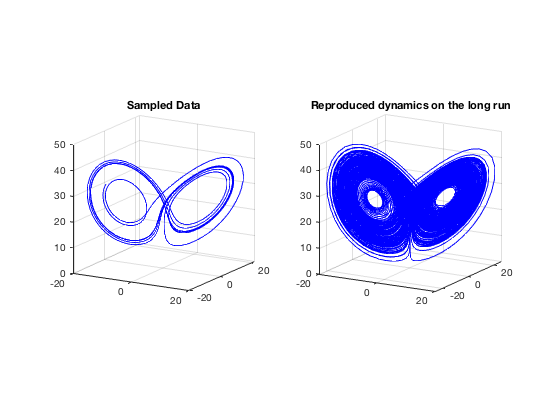

%Re-produced dynamic on the long run
[~,R] = ode45(odefun, [0 200],x0); 

figure
subplot(1,2,1)
plot3(X(:,1),X(:,2),X(:,3),'-b')
view(30,15)
pbaspect([1 1 1])
grid on
title('Sampled Data')

subplot(1,2,2)
plot3(R(:,1),R(:,2),R(:,3),'-b')
view(30,15)
pbaspect([1 1 1])
grid on
title('Reproduced dynamics on the long run')

## Computaions Complexity 

### Information Estimator

We provide two mutual information estimators, the Knn {default}, and the discrete mutual information estimator. And the user can provide his user defined mutual information estimator through the options structure created using $\texttt{eroptset}$ function.

The Knn estimator is more accurate and reliable, however, it can be very expensive for large datasets. We can change the information estimatore as follows:

[Phi,Xdot] = getSystemDataset(@lorenzODE, 'SampleSize', 4000);

% Call erfit with the default (Knn MI estimator)
tic;
S1 = erfit(Phi,Xdot);
time1 = toc;

% Call erfit with the discrete MI estimator
options = eroptset('MIEstimator',@MIDiscrete);
tic;
S2 = erfit(Phi,Xdot,options);
time2 = toc;

we can see that discrete MI estimator is more than 4 times faster than Knn estimator:

disp(time1/time2)

    5.4449



 and this difference grow exponentially with the sample size. However, they both return the same accurate solution:

disp(norm(S1-S2,'fro'))

     0



So, it is a tarde off between the accuracy and the computation complexity. It is recommended to use the discrete MI estimator with data larger than 2000 observations.

### Prior Information

Prio informations about the system can highly reduce the computation complexity. 

For example, many dynamical systems have several linear terms in the set of equations, then, including the linear terms priori in the forward selection can highly reduce the comlixity.

Consider a dataset as follows:

[Phi,Xdot] = getSystemDataset(@lorenzODE, 'SampleSize', 1000);

tic;
S1 = erfit(Phi,Xdot);
time1 = toc;

% Initialize the forward ER with the linear terms
% meaning that, start the forward ER from the linear terms and not from
% empty set
options = eroptset('fkeepin',[1 2 3 4]); 

tic;
S2 = erfit(Phi,Xdot,options);
time2 = toc;

disp(time1/time2)

    1.2825



We can see that the erfit was 1.5 times faster in solving the problem, and this ratio higly increase with the sample size and number of candidate functions.

Moreover, initializing the forward step with the linear terms can boost the accuracy when the problem have high degree of uncertinity. For example, consider the dataset:

[Phi,Xdot,DInfo] = getSystemDataset(@lorenzODE, 'SampleSize', 100);
figure
X = DInfo.Xclean;
plot3(X(:,1),X(:,2),X(:,3),'-b','LineWidth',2)
view(30,15)
axis([-25 25 -25 25 0 50])
pbaspect([1 1 1])
grid on
title('Sampled Data')

We can see that the sampled data is very short, and does not show the dynamics of Lorenz system (the butterfly shape).  Using the default setting of erfit on this data will give the following results:

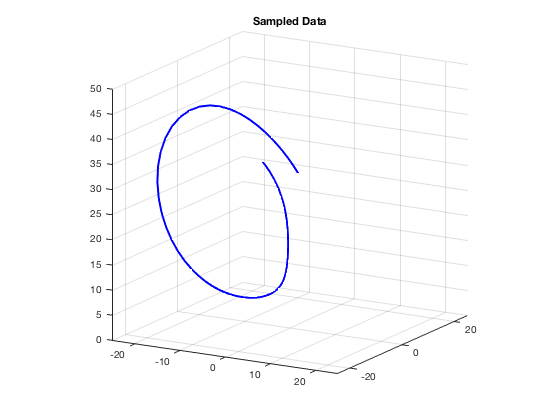

    0.4960    0.2427    0.0721
         0   26.4111         0
    5.0873         0         0
         0         0   -2.6608
         0    0.1465         0
         0         0    0.9947
         0   -0.9166         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
    0.0016         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
        

S = erfit(Phi,Xdot);
disp(S)

Although that we have short dataset, we see that the ER with the default setting was able to recover the first and the last columns of the parameters matrix accurately. Now, by initializaing the forward ER with the linear terms we will have:

options = eroptset('fkeepin',1:4); 
S = erfit(Phi,Xdot,options);
disp(S)

   -0.0163   -0.2516    0.0721
   -9.9778   27.5642         0
    9.9743   -0.8979         0
         0         0   -2.6608
         0         0         0
         0         0    0.9947
         0   -0.9889         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
        

and to check the ability of the estimated solution to reproduce the hidden dynamic we see that:

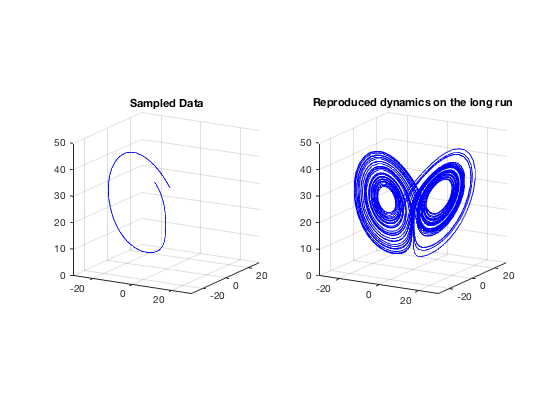

odefun = getODEHandle(DInfo.PowrMatrix, S);
[t,R] = ode45(odefun, [0 50], X(1,:)');

figure
subplot(1,2,1)
plot3(X(:,1),X(:,2),X(:,3),'-b')
view(30,15)
axis([-30 30 -30 30 0 50])
pbaspect([1 1 1])
grid on
title('Sampled Data')

subplot(1,2,2)
plot3(R(:,1),R(:,2),R(:,3),'-b')
view(30,15)
axis([-30 30 -30 30 0 50])
pbaspect([1 1 1])
grid on
title('Reproduced dynamics on the long run')

### Parallel Computations

We provide the option for the user to use parallel computations when resources are available. However, it is only recomended when the dictionary matrix have a very large number of candidate functions ( 100s ). Otherwise, the overhead cost will make it inefficient to use parallel computations.

We can activate parallel computation simply by setting the option:

options = eroptset('useparallel',true);